clc; % czysci command window
clear; %czysci zmienne
close; %zamyka wszystkie okna

## Geometria i geometria odwrotna

Wykres wydłużenia siłownika w funkcji kąta wychylenia steru

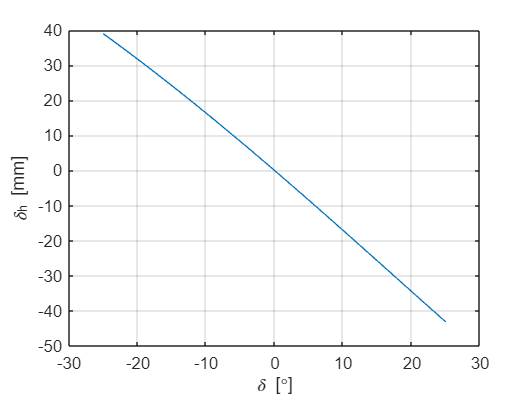

y_max = 100;
L = 180;
R=100;
Y=180;
alpha=asin(R/(2*L));
alpha_prim=pi/2 - alpha;
delta_max = 25;

delta=-25:0.1:25;

delta_h = -(Y-sqrt(L^2+R^2-2*L*R*cos(alpha_prim-delta*pi/180)));

%figure;
plot(delta,delta_h);
grid on
xlabel('\delta [\circ]');
ylabel('\delta_h [mm]');
grid on

%hold on

## Dynamika układu

Zależność siły wzdłużnej w siłowniku od kąta wychylenia steru i momentu aerodynamicznego

v_dzwieku = 340.3;
Ma= 0.3;
v_lotu = v_dzwieku*Ma;
c = 2.37;
rho = 1.2255;
b = 12.45;
wsp1 = 0.5*rho * c^2 * b;
V = (0.1*v_dzwieku:10:0.8*v_dzwieku)';


delta_dyn = [-25, -20, -10, 0, 10, 20, 25];
delta_dyn = deg2rad(delta_dyn);
cm_h = [-0.033139, -0.027379, -0.017291, -0.000038, 0.017291, 0.027379, 0.033139];
M_h = wsp1*cm_h;

    delta_h_dyn = -(Y-sqrt(L^2+R^2-2*L*R.*cos(alpha_prim-delta_dyn)));
    beta = acos((R^2 +delta_h_dyn.*(delta_h_dyn+2*L))./(2*R*(L+delta_h_dyn))) - pi/2;
    R_B = M_h./(R*cos(beta))

R_B =    -0.0175   -0.0138   -0.0081   -0.0000    0.0075    0.0117    0.0143


    
Q = V.^2*R_B

Q = 1.0e+03 *

   -0.0202   -0.0160   -0.0094   -0.0000    0.0087    0.0136    0.0166
   -0.0339   -0.0268   -0.0158   -0.0000    0.0145    0.0228    0.0278
   -0.0510   -0.0404   -0.0237   -0.0000    0.0218    0.0343    0.0418
   -0.0717   -0.0567   -0.0333   -0.0001    0.0306    0.0481    0.0588
   -0.0958   -0.0758   -0.0446   -0.0001    0.0409    0.0644    0.0785
   -0.1235   -0.0977   -0.0574   -0.0001    0.0527    0.0829    0.1012
   -0.1546   -0.1223   -0.0719   -0.0001    0.0660    0.1038    0.1267
   -0.1892   -0.1497   -0.0880   -0.0002    0.0808    0.1271    0.1551
   -0.2273   -0.1799   -0.1057   -0.0002    0.0971    0.1527    0.1863
   -0.2690   -0.2128   -0.1251   -0.0003    0.1149    0.1806    0.2204




%figure;
plot(delta_dyn,R_B,'LineWidth',2);
grid on
xlabel('\delta [\circ]');
ylabel('R_B/v^2 [N/(m/s)^2]');
axis([-pi/6 pi/6 -0.02 0.02])
grid on
hold on
close

## Dane siłownik

A_1 = 5.03*1e-3;     % m^2
A_2 = 1.59*1e-3;     % m^2
m = 10;               % kg
K = 1.8e5;         % Pa
V_1 = 2.26*1e-4;     % m^3
V_2 = 6.68*1e-5;     % m^3

% warunki początkowe

p_01 = 1e6;          % Pa
p_02 = p_01*A_1/A_2; % Pa

x_0 = 0;              %m
xp_0 = 0;             %m/s